Les données

Donnees1 = readmatrix('Donnees_Projet_Optimisation.xlsx','sheet',1);
Donnees2 = readmatrix('Donnees_Projet_Optimisation.xlsx','Sheet',2);
Demandes = Donnees1(:,2); % Demandes(MW)
Heures = Donnees1(:,1);   % Heurs(h)
Unit = Donnees2(:,1);     % Les unités
Pmin = Donnees2(:,4);     % Puissances minimales
Pmax = Donnees2(:,5);     % Puissances maximales
R_Pos = Donnees2(:,6);    % Réserves de puissances positives
R_Neg = Donnees2(:,7);    % Réserves de puissances négatives
RU = Donnees2(:,8);       % Rampes de puissances de positive
RD = Donnees2(:,9);       % Rampes de puissances de négative
MU = Donnees2(:,10);      % Temps minimal de fonctionnement 
MD = Donnees2(:,11);      % Temps minimal d'arrêt

Cp = Donnees2(:,12);      % Couts de production
Cu = Donnees2(:,13);      % Couts de réserve positive
Cd = Donnees2(:,14);      % Couts de réserve négative
Csu = Donnees2(:,15);     % Couts fixe de démarrage
Ce = 74*ones(24,1);       % Cout de l'életricité éolienne
Pinit = Donnees2(:,16);   % Puissances initiales
InitState = Donnees2(:,17); % Etats initiales de fonctionnement
Tini = Donnees2(:,18);     % Temps initiales de fonctionnement
n1 = length(Heures) ;      % nombre d'heures
n2 = length(Unit);         % nombre d'unités

Fonction objectif

f1 = [repmat(Cp,n1,1); zeros(n1*n2,1);repmat(Cu,n1,1);repmat(Cd,n1,1);repmat(Csu,n1,1);zeros(n1*n2,1)];
% f2 = FVAL + Pw*Ce;

Contraintes

% Matrice satisfaction de la demande
C1 = zeros(n1,6*n2*n1);
for k =1:n1
    C1(k,(k-1)*n2+1:k*n2)=-ones(1,n2);
end
% Matrice des états de fonctionnements
C2 = zeros(n1*n2,6*n2*n1);
D2 = repmat(Pmin,n1,1);
for k =1:n1*n2
    C2(k,k)=-ones(1,1);
    C2(k,n1*n2+k)=D2(k);
end
C3 = zeros(n1*n2,6*n2*n1);
D3 = repmat(Pmax,n1,1);
for k =1:n1*n2
    C3(k,k)=ones(1,1);
    C3(k,n1*n2+k)=-D3(k);
end
% Matrice des rampes de puissances
% Rampes positives
D4 = [RU*60 + Pinit;repmat(RU*60,n1-1,1)];
C4 = zeros(n1*n2,6*n2*n1);
for k = 1:n2
    C4(k,k)=ones(1,1);
end
for k =n2+1:n1*n2
    C4(k,k-n2)=-ones(1,1);
    C4(k,k)=ones(1,1);
end
% Rampes négatives
D5 = [RD*60 - Pinit;repmat(RD*60,n1-1,1)];
C5 = zeros(n1*n2,6*n2*n1);
for k = 1:n2
    C5(k,k)=-ones(1,1);
end
for k =n2+1:n1*n2
    C5(k,k-n2)=ones(1,1);
    C5(k,k)=-ones(1,1);
end
% Matrices des reserves positives et négatives
% Réserve positive
C6 = zeros(n1*n2,6*n2*n1);
for k =1:n1*n2
    C6(k,k)=ones(1,1);
    C6(k,2*n1*n2+k)=ones(1,1);
    C6(k,n1*n2+k)=-D3(k);
end
% Réserve Négative
C7 = zeros(n1*n2,6*n2*n1);
for k =1:n1*n2
    C7(k,k)=-ones(1,1);
    C7(k,3*n1*n2+k)=ones(1,1);
    C7(k,n1*n2+k)=D2(k);
end
% Matrices staisfaction de la demande de la reserve
C8 = zeros(n1,6*n2*n1);
for k =1:n1
    C8(k,2*n1*n2+(k-1)*n2+1:2*n1*n2+k*n2)=-ones(1,n2);
end
C9 = zeros(n1,6*n2*n1);
for k =1:n1
    C9(k,3*n1*n2+(k-1)*n2+1:3*n1*n2+k*n2)=-ones(1,n2);
end
% Matrices de démarrage et d'arrêt
D10 = [-InitState; repmat(zeros(n2,1),n1-1,1)];
C10 = zeros(n1,6*n2*n1);
for k =1:n2
    C10(k,n1*n2+k)=-ones(1,1);
    C10(k,4*n1*n2+k)=ones(1,1);
    C10(k,5*n1*n2+k)=-ones(1,1);
end
for k =n2+1:n1*n2
    C10(k,n1*n2+k)=-ones(1,1);
    C10(k,4*n1*n2+k)=ones(1,1);
    C10(k,5*n1*n2+k)=-ones(1,1);
    C10(k,n1*n2+k-n2)=ones(1,1);
end
% Calcul de Puissance éolienne
Pw = [];
Vw = wblrnd(7.2,2.15,24,1);
Pr = 2;
Vci = 3.5;
Vr = 14;
Vco = 25;
n3= length(Vw);
for k = 1:n3
    if Vw(k) <= Vci | Vw(k) >= Vco 
        Pw(k)=0;
    elseif Vw(k)>= Vr && Vw(k)<= Vco
        Pw(k)=Pr*10;
    else 
        Pw(k) = 10*Pr*((Vw(k)^3-Vci^3 )/ (Vr^3 - Vci^3 ));
    end
end
% Matrices inégalités linéaires

Aineq = [C1;C2;C3;C4;C5;C6;C7;C8;C9];
bineq = [-Demandes+Pw';zeros(2*n1*n2,1);D4;D5;zeros(2*n1*n2,1);0.1*(-Demandes);0.1*(-Demandes)];

% contraintes égalités linéaires

Aeq =[C10];
Beq =[D10];

% Définition des bornes
lb = [zeros(6*n1*n2,1)];
ub = [repmat(Pmax,n1,1);ones(n1*n2,1);repmat(R_Pos,n1,1);repmat(R_Neg,n1,1);ones(2*n1*n2,1)];
intcon=n1*n2+1:2*n1*n2;

Solveur

opt = optimoptions('intlinprog','Display','iter');
[X,FVAL,EXITFLAG,OUTPUT]= intlinprog(f1,intcon,Aineq,bineq,Aeq,Beq,lb,ub,opt);

LP:                Optimal objective value is 553740.478419.                                        

Cut Generation:    Applied 17 Gomory cuts,                                                          
                   154 implication cuts, 61 flow cover cuts,                                        
                   and 4 clique cuts.                                                               
                   Lower bound is 567551.743985.                                                    

Heuristics:        Found 2 solutions using diving.                                                  
                   Upper bound is 569309.941622.                                                    
                   Relative gap is 0.31%.                                                          

Heuristics:        Found 1 solution using ZI round.                                                 
                   Upper bound is 567863.668928.                                         

Extraction de valeurs pour la visualisation de certaines centrales

Result = [X(1:n1*n2) X(2*n1*n2+1:3*n1*n2) X(3*n1*n2+1:4*n1*n2) X(n1*n2+1:2*n1*n2) X(4*n1*n2+1:5*n1*n2) X(5*n1*n2+1:6*n1*n2)];
Sol_H4 = Result(37:48,1:3);
Co_H4 = Result(37:48,1:3).*[Cp Cu Cd]; % Couts de la solution à la quatrième heure
Unit13 = [];                           % Valeurs de l'unité 13 sur toute la journée
etat = [];                             % Etats de l'unité 13 sur toute la journée
etat1 = [];                            % Etats de l'unité 1 sur toute la journée
ReserPUnit13 = [];                     % Valeurs de la réserve positive l'unité 13 sur toute la journée
ReserNUnit13=[];                       % Valeurs de la réserve négative l'unité 13 sur toute la journée
for k = 1:n1
    Unit13(k)=X(n2*(k-1)+1);
    etat(k)=X(n1*n2+ n2*(k-1)+4);
    etat1(k)=X(n1*n2+ n2*(k-1)+1);
    ReserPUnit13(k) = X(2*n1*n2 + n2*(k-1)+4);
    ReserNUnit13(k) = X(3*n1*n2 + n2*(k-1)+4);
end


Graphes

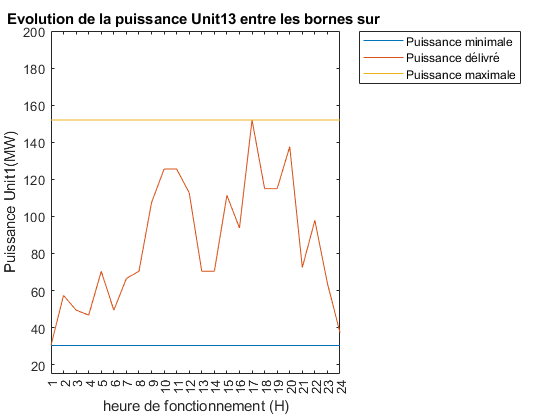

% Représentation des puissances entre les bornes de puissances
figure
plot(Heures,ones(24,1)*Pmin(1),Heures,Unit13,Heures,ones(24,1)*Pmax(1));
xlim([1 24])
xticks([1:1:24])
ylim([15 200])
xlabel('heure de fonctionnement (H)')
ylabel(['Puissance Unit1(MW)'])
title(sprintf(['Evolution de la puissance Unit13 entre les bornes sur ']))
legend('Puissance minimale','Puissance délivré','Puissance maximale','Location','bestoutside')

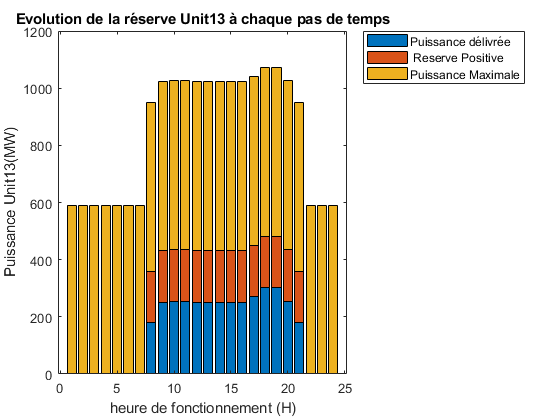

% Représentation des puissances entre les réserves de puissances
figure
Reserv = [Unit1'  ReserPUnit' ones(24,1)*Pmax(4)' ];
bar(Heures,Reserv,'stacked');
xlabel('heure de fonctionnement (H)')
ylabel(['Puissance Unit13(MW)'])
title(sprintf(['Evolution de la réserve Unit13 à chaque pas de temps']))
legend('Puissance délivrée',' Reserve Positive','Puissance Maximale','Location','bestoutside')

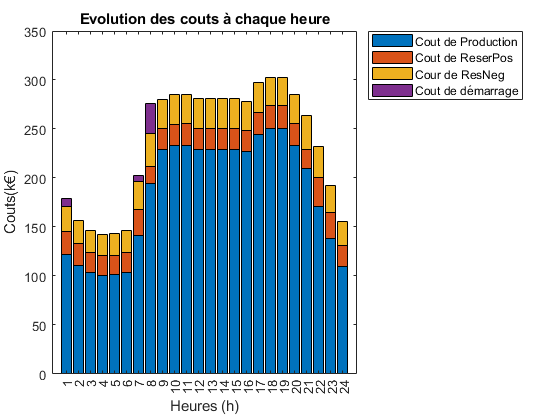

figure
Cout_Total = [];
for j = 1:n1
    Cout_Total1 = [X(1+n2*(j-1):j*n2)'*Cp  X(2*n1*n2+1+n2*(j-1):2*n1*n2+j*n2)'*Cu...
                   X(3*n1*n2+1+n2*(j-1):3*n1*n2+j*n2)'*Cd  X(4*n1*n2+1+n2*(j-1):4*n1*n2+j*n2)'*Csu];
    Cout_Total = [Cout_Total;Cout_Total1];
end
bar(1:24,Cout_Total*10e-3,'stacked')
xticks([1:1:24])
xlabel('Heures (h)')
ylabel('Couts(k€)')
title(sprintf(['Evolution des couts à chaque heure']))
legend('Cout de Production','Cout de ReserPos','Cour de ResNeg','Cout de démarrage','Location','bestoutside')

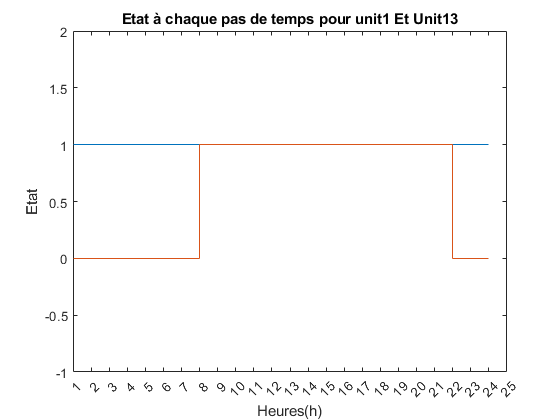

% Representation des etats
etats= [etat1' etat'];
figure
stairs(Heures,etats)
xticks([0:1:25]);
xlim([1 25])
ylim([-1 2]);
xlabel('Heures(h)')
ylabel('Etat')
title('Etat à chaque pas de temps pour unit1 Et Unit13')